Load in data from the work space

data=readtable("dataClean.csv");


electrical_load = data.DC;

% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [data.DC(1:end-1)];

T = data.DC(2:end);
% 
% for i = 1:(n -  1)
%     idx=1+(i-1)*input_window_size;
%     X(:,i) =  electrical_load(idx:idx + input_window_size - 1)';
%     T(:,i) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
% end


% Split data into training and testing sets
train_ratio = 0.7;
num_train = floor(length(X) * train_ratio);
X_train = X(1:num_train);
T_train = T(1:num_train);
X_test = X(num_train+1:end);
T_test = T(num_train+1:end);

% Create and Train Neural Network

opt = struct("ShowPlots",true,"MaxObjectiveEvaluations",100);

% Define hyperparameters to optimize
params = hyperparameters("fitrnet",X_train,"MPG");
for ii = 1:length(params)
    disp(ii);disp(params(ii))
end

     1

  optimizableVariable with properties:

         Name: 'NumLayers'
        Range: [1 3]
         Type: 'integer'
    Transform: 'none'
     Optimize: 1

     2

  optimizableVariable with properties:

         Name: 'Activations'
        Range: {'relu'  'tanh'  'sigmoid'  'none'}
         Type: 'categorical'
    Transform: 'none'
     Optimize: 1

     3

  optimizableVariable with properties:

         Name: 'Standardize'
        Range: {'true'  'false'}
         Type: 'categorical'
    Transform: 'none'
     Optimize: 1

     4

  optimizableVariable with properties:

         Name: 'Lambda'
        Range: [1.6311e-09 16.3106]
         Type: 'real'
    Transform: 'log'
     Opt

|============================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | Initializer  | nitializer   |                       |
|============================================================================================================================================|
|    1 | Best   |      7.5879 |      2.1236 |      7.5879 |      7.5879 |   1.6446e-07 |       glorot |         ones | [ 20 231   2 284]     |
|    2 | Best   |      5.2504 |      94.889 |      5.2504 |      6.3697 |   0.00015011 |           he |        zeros | [ 68 137   2  38]     |
|    3 | Best   |      5.2396 |      90.066 |      5.2396 |      5.3011 |   1.9492e-08 |           he |         ones | [ 69 197]             |

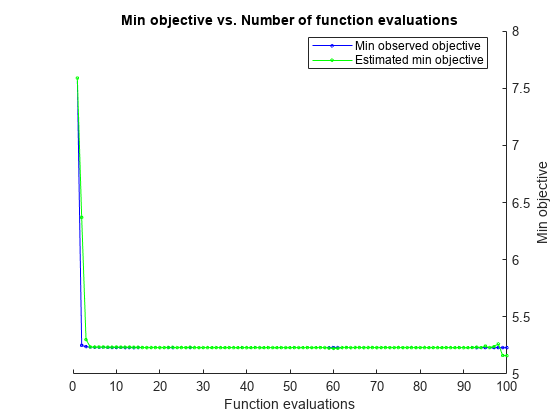


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 2760.7248 seconds
Total objective function evaluation time: 2693.1295

Best observed feasible point:
    Lambda     LayerWeightsInitializer    LayerBiasesInitializer              LayerSizes          
    _______    _______________________    ______________________    ______________________________

    0.12616              he                        ones             34      4    130      9      4

Observed objective function value = 5.2309
Estimated objective function value = 5.2874
Function evaluation time = 63.7487

Best estimated feasible point (according to models):
     Lambda     LayerWeightsInitializer    LayerBiasesInitializer


params(1).Range = [1 5] ;

params(2).Optimize = false ;

params(3).Optimize = false;

params(5).Optimize = true;
params(6).Optimize = true;
params(10).Optimize = true;
params(11).Optimize = true;
% Fit the network using hyperparameter optimization
net = fitrnet(X_train, T_train, ...
    'Standardize', true, ...
    'Activations', 'relu', ...
    'OptimizeHyperparameters', params, ...
    'HyperparameterOptimizationOptions', opt);

net

net =   RegressionNeuralNetwork
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 6131
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           LayerSizes: [1 24]
                          Activations: 'relu'
                OutputLayerActivation: 'none'
                               Solver: 'LBFGS'
                      ConvergenceInfo: [1×1 struct]
                      TrainingHistory: [313×7 table]


  Properties, Methods


% Perform Forecast


timeStep= 1;
for j = 1:(floor(length(X_test)/timeStep)-ceil(24/timeStep)-71)
   
    offset = j*timeStep+71 ;
    
    input = X_test(1:offset); 
    first_forecast = predict(net, input);
    Yin = first_forecast(end:end);
    Y = zeros(24,1);
    Y(1) = Yin;
      
    for i=2:24
        input = [input(2:end)' Y(i-1)'];
        input = input';
        YNext = predict(net, input);
        Y(i)  = [YNext(end:end)];

    end
    
    Ypred{j}(:) = Y(:);
    Yactual{j}(:) = T_test(offset:offset+23);
end

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);

for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;

YintMape(i) = (abs(trapz(Yactual{i}) - trapz(Ypred{i}))/(trapz(Yactual{i})))*100;

YintRmse(i) = ((trapz(Yactual{i})-trapz(Ypred{i}))/24)^2;

YintTotalRmse(i) = ((trapz(Yactual{i})-trapz(Ypred{i})))^2;


end


YmapeHr = YmapeHr./j;
Yrmse = sqrt(YseCal./j);

yMeanRmse = sqrt(mean(YseCal./j));

DCintMape = mean(YintMape)

DCintMape = 25.4569

DCintRmse = sqrt(mean(YintRmse))

DCintRmse = 23.5186

DCtotalIntRmse = sqrt(mean(YintTotalRmse))

DCtotalIntRmse = 564.4471

hourlyDCmape = YmapeHr

hourlyDCmape =     7.3978
   13.2775
   18.5416
   23.4663
   28.2471
   32.6842
   36.6653
   40.1590
   42.7547
   44.5467


hourlyDCrmse = Yrmse

hourlyDCrmse =    12.3745
   20.9904
   27.6146
   32.9612
   37.3406
   41.0784
   44.0782
   46.3862
   47.7703
   48.2335


DCrmseMean = yMeanRmse

DCrmseMean = 39.8875


save('NN_DC', 'hourlyDCmape','hourlyDCrmse','DCrmseMean','DCintMape','DCintRmse','DCtotalIntRmse')

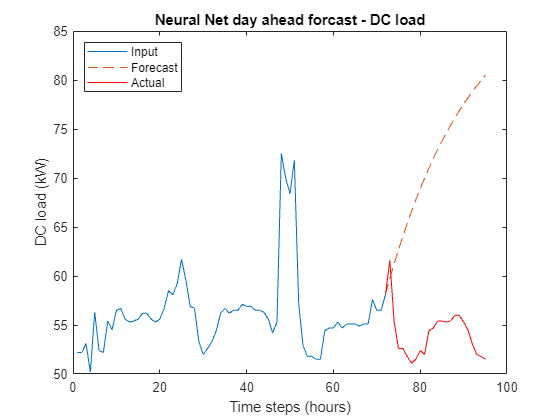


plot(1:72 , T_test(1:72))

hold on
plot(72:95, Ypred{1},"--")
plot(72:95, Yactual{1},"r")

ylabel("DC load (kW)")
xlabel("Time steps (hours)")
title("Neural Net day ahead forcast - DC load")
legend("Input", "Forecast", "Actual", "Location","northwest")

hold off

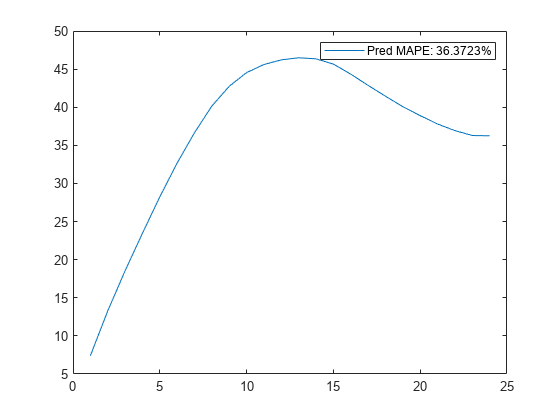




plot(YmapeHr)
legend("Pred MAPE: " + mean(YmapeHr) +"%")

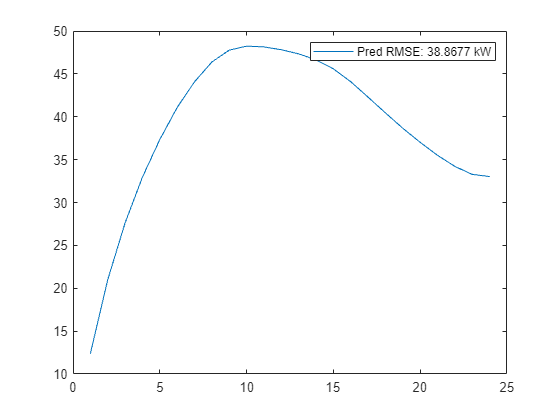


plot(Yrmse)
legend("Pred RMSE: " + mean(Yrmse) +" kW")